在单 GPU 上训练。
正在初始化输入数据归一化。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量　ＲＭＳＥ　　｜　　验证　ＲＭＳＥ　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０１　｜　　　　　　３３．７０　｜　　　　　　１．４１　｜　５６７．７４８５　｜　０．９９５４　｜　　０．０１００　｜
｜　　　５　｜　　　５０　｜　　　　　００：００：０５　｜　　　　　　　０．８８　｜　　　　　　７．４８　｜　　０．３８９７　｜　２７．９５４５　｜　　０．０１００　｜
｜　　１０　｜　　１００　｜　　　　　００：００：０８　｜　　　　　　　３．２８　｜　　　　　　２．２２　｜　　５．３７３７　｜　２．４６２１　｜　　０．０１００　｜
｜　　１４　｜　　１５０　｜　　　　　００：００：１１　｜　　　　　　２３．８５　｜　　　　　１７．５９　｜　２８４．４０３２　｜　１５４．６４９４　｜　　０．０１００　｜
｜　　１９　｜　　２００　｜　　　　　００：００：１４　｜　　　　　　　０．７９　｜　　　　　　０．６４　｜　　０．３１１４　｜　０．２０７１　｜　　０．００２０　｜
｜　　２３　｜　　２５０　｜　　　　　００：００：１８　｜　　　　　　　１．１２　｜　　　　　　２．００　｜　　０．６２２６　｜　１．９９８３　｜　　０．００２０　｜
｜　　２８　｜　　３００　｜　　　　　００：００：２１　｜　　　　　　　０．２９　｜　　　　　　０．３７　｜　　０．０４１６　｜　０．０６８０　｜　　０．００２０　｜
｜　　３０　｜　　３３０　｜　　　　　００：００：２２　｜　　　　　　　０．３４　｜　　　

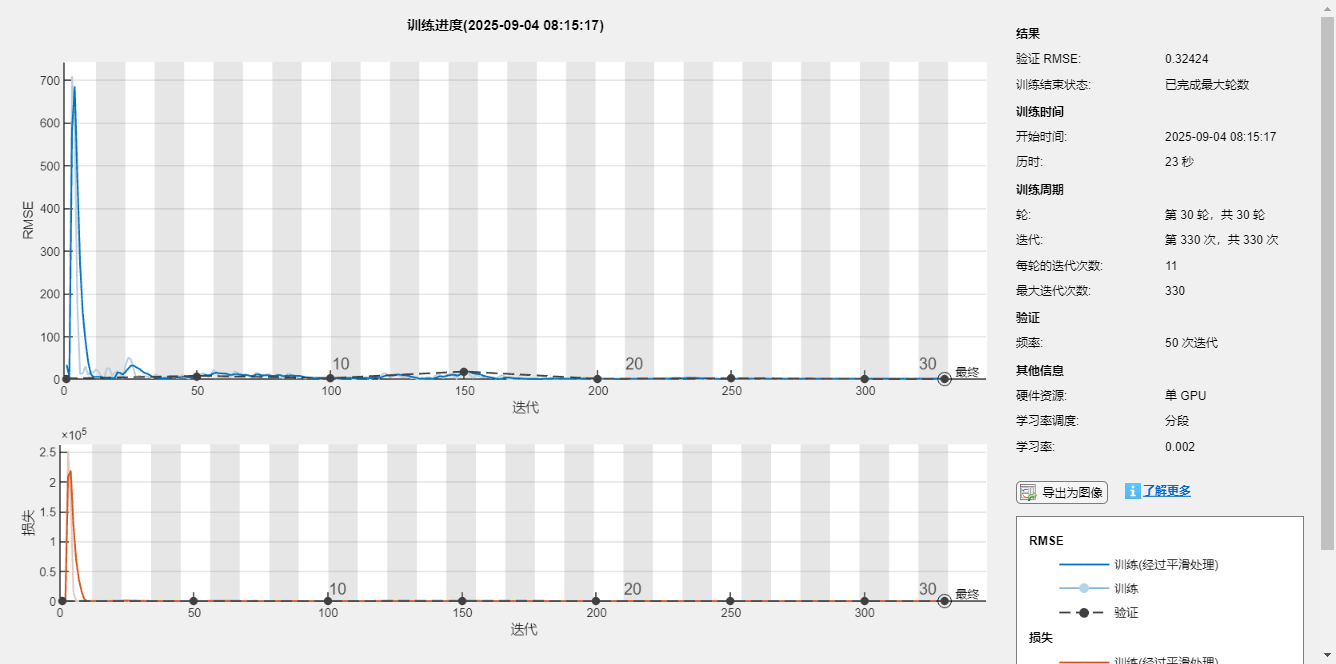

%% 1. 数据加载与预处理 (与之前相同)
clear
clc
addpath(genpath('G:\EIS'))
filenames = {'EIS_state_V_35C02.txt','Data_Capacity_35C02.txt'};
EIS_Data = importdata(filenames{1});
CapacityData = importdata(filenames{2});
CapacityData = CapacityData.data;
CycleNum = min(max(EIS_Data(:,2)),max(CapacityData(:,2)));
Capacity = cell(1,CycleNum);
EISData = cell(1,CycleNum);

for kk = 1:CycleNum
    z = find(EIS_Data(:,2)==kk);
    z1 = find(CapacityData(:,2)==kk-1);
    SubEISData = EIS_Data(z,4:7);
    SubEISData = mat2cell(SubEISData,60,4);
    SubCapacity = CapacityData(z1,:);
    SubCapacity= SubCapacity(end,end);
    Capacity(kk) = num2cell(SubCapacity);
    EISData(kk) = SubEISData;
end

k=0.6;
TrainX_cell = EISData(1:round(k*CycleNum));
TrainY_cell = Capacity(1:round(k*CycleNum));
TestX_cell = EISData(1+round(k*CycleNum):end);
TestY_cell = Capacity(1+round(k*CycleNum):end);

%% 2. 【关键修改】转换数据格式
% 将 cell 数组转换为 4-D 数字数组
% 维度变为: [Height, Width, Channels, NumSamples] -> [60, 4, 1, NumTrainSamples]
TrainX = cat(4, TrainX_cell{:});
TestX = cat(4, TestX_cell{:});

% 将 cell 数组转换为列向量
TrainY = cell2mat(TrainY_cell)';
TestY = cell2mat(TestY_cell)';


%% 3. 【关键修改】设置新的网络结构
InputSize = [60,4,1];
FilterSize = [3,3] ;Filters = 15;
layers = [
    % 使用 imageInputLayer 而不是 sequenceInputLayer
    imageInputLayer(InputSize,'Name','input') 
    
    convolution2dLayer(FilterSize,Filters,Padding="same",Name='con2d-1')
    averagePooling2dLayer([3,3])
    reluLayer(Name='relu')
    flattenLayer(Name='flatten')
    selfAttentionLayer(7,35)
    reluLayer
    fullyConnectedLayer(320,Name='fc1')
    reluLayer
    fullyConnectedLayer(160,Name='fc2');reluLayer
    fullyConnectedLayer(80,Name='fc3');reluLayer
    fullyConnectedLayer(1,Name='fc4')
    regressionLayer
];
graph = layerGraph(layers);

%% 4. 重新训练模型
options = trainingOptions("adam",...
    "Plots",'training-progress',... %打开以观察训练
    'MaxEpochs',30,...
    'Shuffle','every-epoch',...
    'InitialLearnRate',0.01,...
    'LearnRateSchedule','piecewise',...
    'GradientThreshold',1,...
    'LearnRateDropPeriod',15,...
    'MiniBatchSize',16,...
    'LearnRateDropFactor',0.2,'ExecutionEnvironment','auto',...
     'ValidationData',{TestX,TestY});
 
model  = trainNetwork(TrainX,TrainY,graph,options);


%% 5. 预测与评估 (代码稍作调整以适应新数据格式)
predictTrain = predict(model,TrainX);
predictTest = predict(model,TestX);
TrainSOH = TrainY./45;
TestSOH = TestY./45;
PredictTrainSOH = predictTrain./45;
PredictTestSOH = predictTest./45;

% ... (绘图和评估代码可以放在这里，不在绘制) ...

%% 6. 【现在可以成功运行】Grad-CAM 分析
fprintf('\n开始执行 Grad-CAM 分析...\n');


开始执行 Grad-CAM 分析...


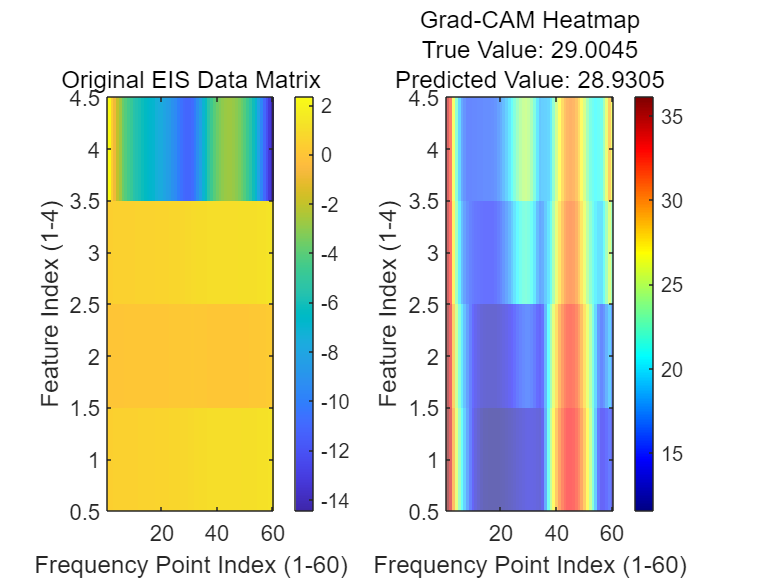

testIdx = 51;
% 从 4-D 数组中提取单个样本
testDataSample = TestX(:,:,:,testIdx); 
trueValue = TestY(testIdx);

% 现在 predict 函数可以直接处理 4-D 数组的单个样本
predictedValue = predict(model, testDataSample);

featureLayer = 'relu';
reductionLayer = 'fc4';
reductionFcn = @(x)x;

% gradCAM 现在可以正确工作
scoreMap = gradCAM(model,testDataSample,reductionFcn, ...
    'ReductionLayer',reductionLayer, ...
    'FeatureLayer',featureLayer);

% 使用上一节中建议的、更合适的可视化方法
figure('Name','Grad-CAM Analysis');
ax(1) = subplot(1,2,1);
imagesc(testDataSample'); % 转置以获得更直观的视图
colorbar;
xlabel('Frequency Point Index (1-60)');
ylabel('Feature Index (1-4)');
title('Original EIS Data Matrix');
set(gca, 'FontSize', 18, 'YDir', 'normal','FontName','Times New Roman');

ax(2) = subplot(1,2,2);
imagesc(imresize(scoreMap', size(testDataSample')), 'AlphaData', 0.6); % 转置并调整大小
colorbar;
xlabel('Frequency Point Index (1-60)');
ylabel('Feature Index (1-4)');
title({['Grad-CAM Heatmap'], ...
       ['True Value: ' num2str(trueValue)], ...
       ['Predicted Value: ' num2str(predictedValue)]});
colormap(ax(2), 'jet');
set(gca, 'FontSize', 18, 'YDir', 'normal','FontName','Times New Roman');